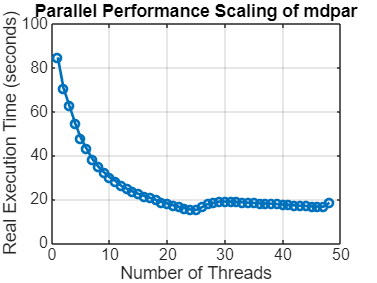

% MATLAB script to read SLURM .out file and plot performance scaling

% Define the filename
filename = 'Parallel1.out'; % Change this to your actual file name

% Open the file for reading
fid = fopen(filename, 'r');
if fid == -1
    error('Error opening the file.');
end

% Initialize arrays to store data
threads = [];
real_time = [];

% Read the file line by line
while ~feof(fid)
    line = fgetl(fid);
    
    % Check if the line contains the thread count
    thread_match = regexp(line, 'Running mdpar with (\d+) threads', 'tokens');
    if ~isempty(thread_match)
        threads = [threads; str2double(thread_match{1}{1})];
    end

    % Check if the line contains the real execution time
    time_match = regexp(line, 'real\s+(\d+)m([\d.]+)s', 'tokens');
    if ~isempty(time_match)
        minutes = str2double(time_match{1}{1});
        seconds = str2double(time_match{1}{2});
        real_time = [real_time; minutes * 60 + seconds]; % Convert to total seconds
    end
end

% Close the file
fclose(fid);

% Plot the results
figure;
plot(threads, real_time, '-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Number of Threads');
ylabel('Real Execution Time (seconds)');
title('Parallel Performance Scaling of mdpar');
grid on;
set(gca, 'FontSize', 12);

% Optional: Save the plot
saveas(gcf, 'mdpar_scaling_plot.png');